# Chest Scan Image Pre-Processing

K = 3;  % for K-means

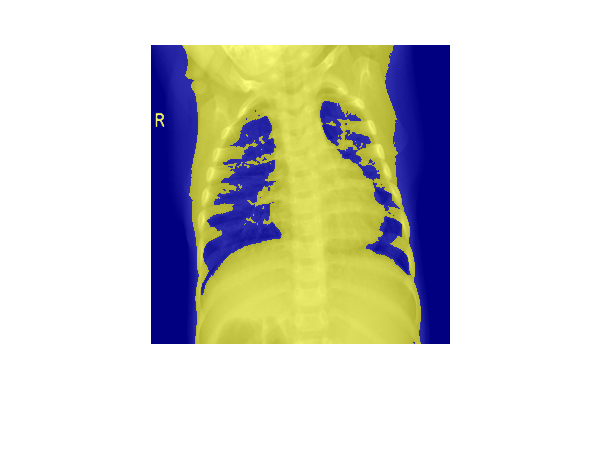

% Class - normal images
num_images = 500; % number of images in dataset is 10192
normal_img = zeros((299*299),num_images);   % Initialize empty array
for i = 1:num_images
    filename = sprintf('./data/normal/Normal-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    img2 = imsegkmeans(img,K);
    normal_img(:,i) = double(reshape(img2,[],1));    % reshapes image as column vector
end                                                 % and adds it to normal_img
labels(1:num_images,1) = "normal";
B = labeloverlay(img, img2);    % test, just displays last img before reshape
imshow(B);

% Class - COVID
num_images2 = 500; % number of images in dataset is 3615
cov_img = zeros((299*299),num_images2);  % Initialize empty array
for i = 1:num_images2
    filename = sprintf('./data/COVID/COVID-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    img2 = imsegkmeans(img,K);
    cov_img(:,i) = double(reshape(img2,[],1));       % reshapes image as column vector
end                                                 % and adds it to cov_img
labels(num_images+1:num_images2+num_images,1) = "COVID";
B = labeloverlay(img, img2);    % test, just displays last img before reshape

B = 299×299×3 uint8 array
B(:,:,1) =

    36    29    28    29    30    30    29    28    28    27    26    24    23    20    18    18    16    15    16    21    23    24    23    24    25    25    25    25    25    25    25    24    23    23    23    22    21    21    20    20    19    20    19    19    18    16    16    17    17    16    14    13    12    12    11    10    10    10    10     9     8     8     8     6     6     5     5     5     4     3     3     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     3     4     6     7     9    11    15    21    32    39    49    56    58    60    63    66   196   200   203   206   207   207   208   209   211   212   212   213   215   218   222   224   224   225   225   227   227   227   228   228   226   225   224   225   225   226   225   225   224   222   223   222   222   221   219   217   216   217   219   221   223   226   226  

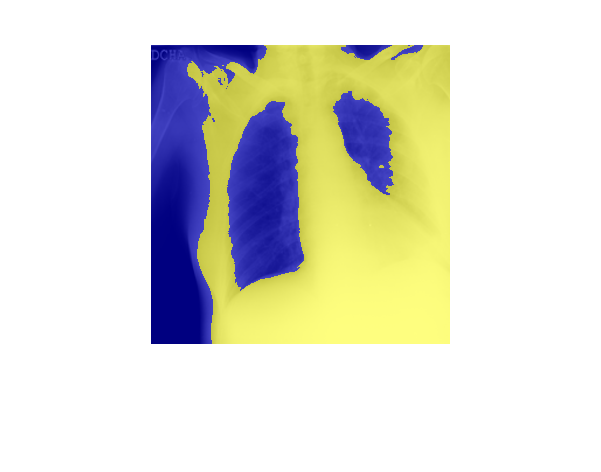

imshow(B);

% Combine images and labels
train_images = [normal_img, cov_img];
train_labels = labels;

%% Train and find the PCA dimensions of the training data
% First reduce the training data to a computationally manageable size
% (note: in this instance, size is unchanged, but may adjust as needed)
train_size = num_images + num_images2;
base = 50;         % Base size, given
% Reduced variables are for if we reduce the number if pics taken from
% dataset.
train_images_reduced = train_images(:,[1:train_size]);
train_labels_reduced = train_labels([1:train_size],:);
% Normalize the data, will be calling it X for simplicity
X = train_images_reduced;
Xmean = mean(X);    % mean of X
Xnorm = X - Xmean;  % normalized
% Calculate covariance matrix
covar_matrix = (Xnorm' * Xnorm) / (train_size - 1);
% Calculate Eigenvectors and Eigenvalues of Covariance Matrix
[Xeivec, Xeival] = eig(covar_matrix);
% Now project the dataset
proj_train = Xnorm * Xeivec;
% Back into larger data format
Xnormk_train = proj_train * Xeivec';

% Create a model with standard params
Mdl = fitcecoc(Xnormk_train',train_labels_reduced');

% Check inital error
error = resubLoss(Mdl)

error = 0

K=2 gives 30% error after kfoldloss, 0% before kfoldloss

% Cross validate, obtain better error numbers
t = templateSVM('Standardize',true);
Mdl2 = fitcecoc(Xnormk_train',train_labels_reduced',...
    'Learners',t,'ClassNames',{'normal','COVID'});
options = statset('UseParallel',true);
CVMdl = crossval(Mdl2,'Options',options);
genError = kfoldLoss(CVMdl)

genError = 0.3010